# Dynamic height from TS observation

close all
clear all

% get data
lat=ncread('woa18_decav_s00_01.nc','lat');
lon=ncread('woa18_decav_s00_01.nc','lon');
lev=ncread('woa18_decav_s00_01.nc','depth');
temp=ncread('woa18_decav_t00_01.nc','t_an');
salt=ncread('woa18_decav_s00_01.nc','s_an');

% set up LONG, LAT and P in 3D array
[ym,xm]=meshgrid(lat,lon);
LONG=repmat(xm,[1 1 102]);
LAT=repmat(ym,[1 1 102]);
lev2(1,1,:)=lev;
P=repmat(lev2,[360 180 1]);

% calculate SA and CT
sa=gsw_SA_from_SP(salt,P,LONG,LAT);
ct=gsw_CT_from_t(sa,temp,P);

% calculate dynamic height (geopotential = gZ) wrt 2000 dbar 
gZ = geo_strf_dyn_height_xyz(sa,ct,P,2000);
Z=gZ/9.8;

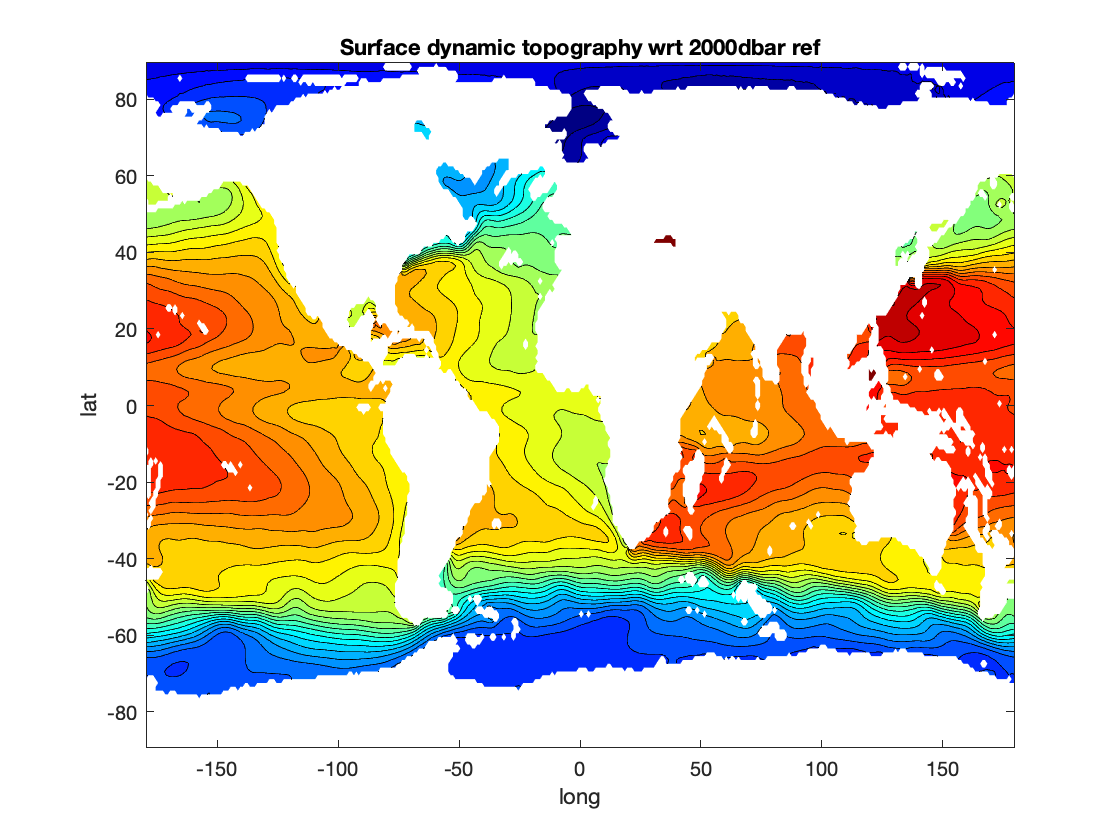

% plot surface dynamic height wrt 2000 dbar
cnt=-1:.1:3;
contourf(xm,ym,Z(:,:,1),cnt);
xlabel('long');
ylabel('lat');
colormap(jet);
title('Surface dynamic topography wrt 2000dbar ref');